# **TU: Decision Tree**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

Author: Jin Kwak/21900031

Date: 24.09.20

## Introduction

Classification with decision tree

## Example

### Dataset :  CWRU dataset features

- Given dataset contains many features extracted from CWRU dataset

- We will select 2~3 features for exercise

clear all;

%% Train
addpath("../../Dataset/CWRU_selected_Dataset/Feature_data/");
load("sample_train.mat");
feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor
X(:, 1) = table2array(glob_all_train(:, feature1));
X(:, 2) = table2array(glob_all_train(:, feature2));
Y = class_cwru_train;       % fault class
N = size(X,1);
tbl=table(X(:, 1),X(:, 2),Y);

%% Test
load("../../Dataset/CWRU_selected_dataset/Feature_data/sample_test.mat");
Xtest(:, 1) = table2array(glob_all_test(:, feature1));
Xtest(:, 2) = table2array(glob_all_test(:, feature2));
Ytest = class_cwru_test;                                 
Ntest=size(Xtest,1);
tblTest=table(Xtest(:, 1),Xtest(:, 2),Ytest);

#### Plot Test Data

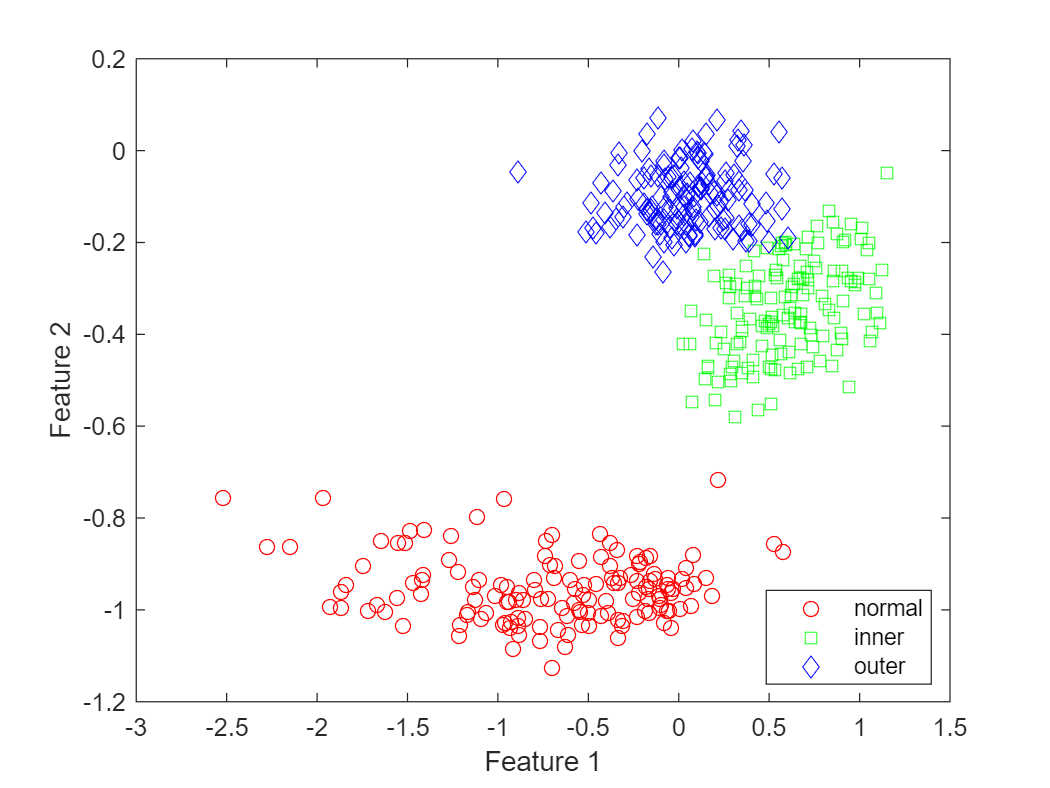

f = figure;
gscatter(X(:, 1), X(:, 2), Y,'rgb','osd');
xlabel('Feature 1')
ylabel('Feature 2')

### Prepare Cross-Validation Data

 `cvpartition` to generate 10 disjoint stratified subsets.

rng(0)
cv = cvpartition(Y,'KFold',10)  %k-fold

cv = K-겹 교차 검증 분할
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

### Fit decision Tree

t = fitctree(X, Y,'PredictorNames',{'SV' 'IF' });

### **Anlayze (Train Data)**

**Resubstitution error**:  misclassification error  on the training set.

test_resub = resubLoss(t)

test_resub = 0.0023

**Confusion matrix** on the training set

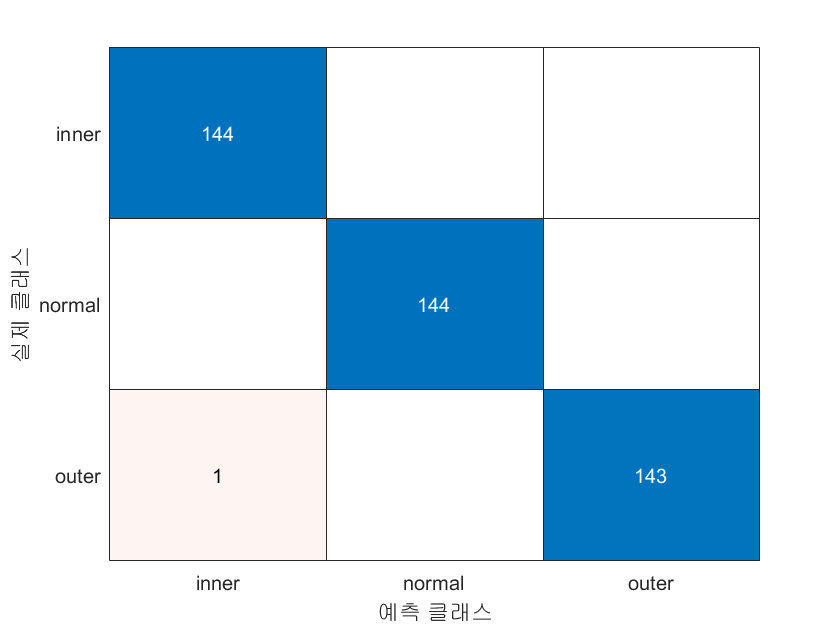

test_class = resubPredict(t);
figure
tResubCM = confusionchart(Y,test_class);

**Misclassification Plot**

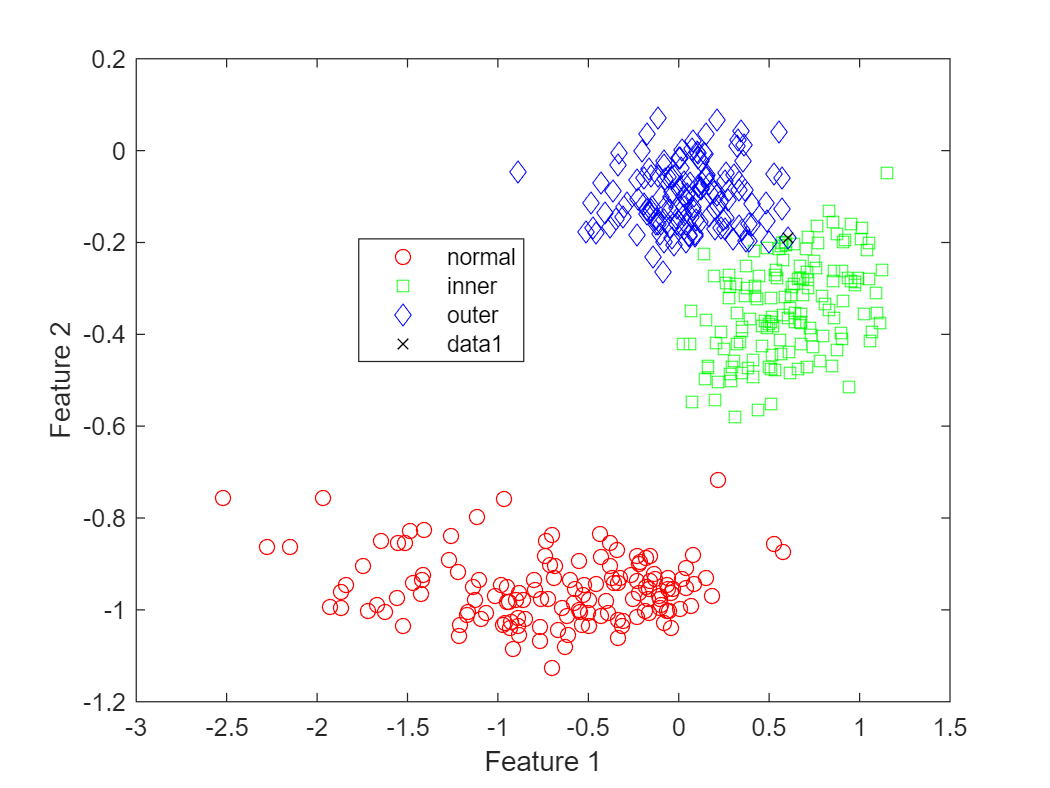

figure(f)
bad = ~strcmp(test_class,Y);
hold on;
plot(X(bad,1), X(bad,2), 'kx');
hold off;

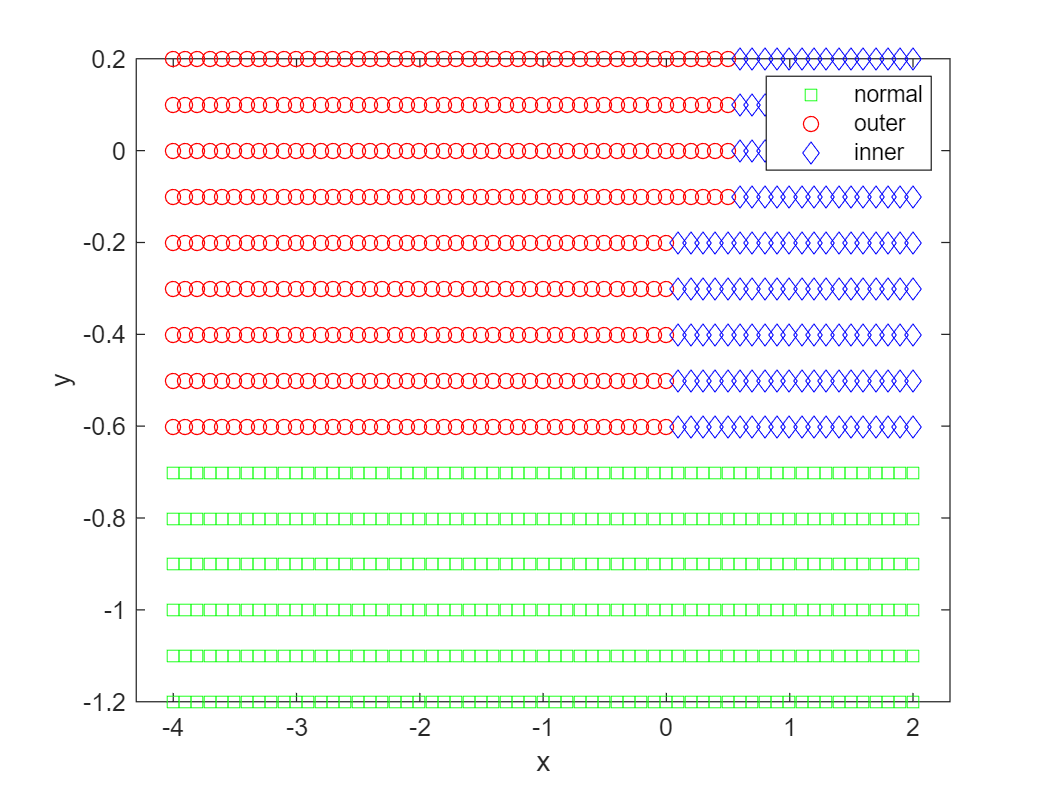

% Visualize Separation regions 
[x,y] = meshgrid(-4:.1:2,-1.2:.1:0.2);
x = x(:);
y = y(:);
[grpname,node] = predict(t,[x y]);
gscatter(x,y,grpname,'grb','sod')

### **Validation (CV)**

Estimate the true test error for LDA using 10-fold stratified cross-validation.

cvt = crossval(t,'CVPartition',cv);
tCVErr = kfoldLoss(cvt)

tCVErr = 0.0069

**visualize the decision tree **

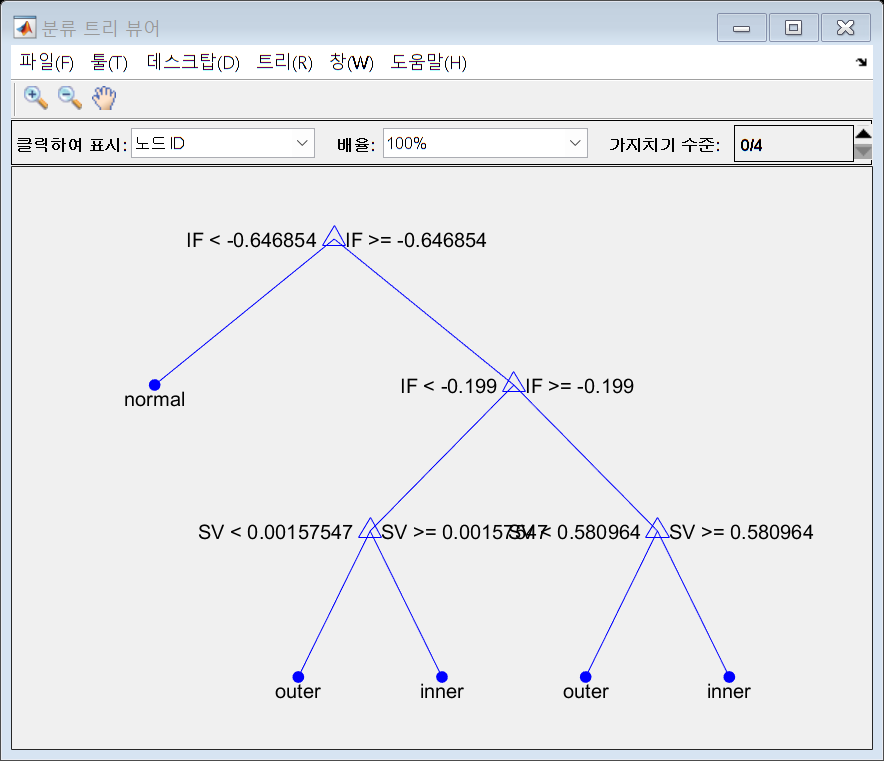

view(t,'Mode','graph');

**Prune tree nodes to enhance result**

- First compute the resubstitution error for various subsets of the original tree. 

- Then compute the cross-validation error for these sub-trees. 

resub_loss = resubLoss(t,'Subtrees','all')

resub_loss =     0.0023
    0.0093
    0.0347
    0.3333
    0.6667


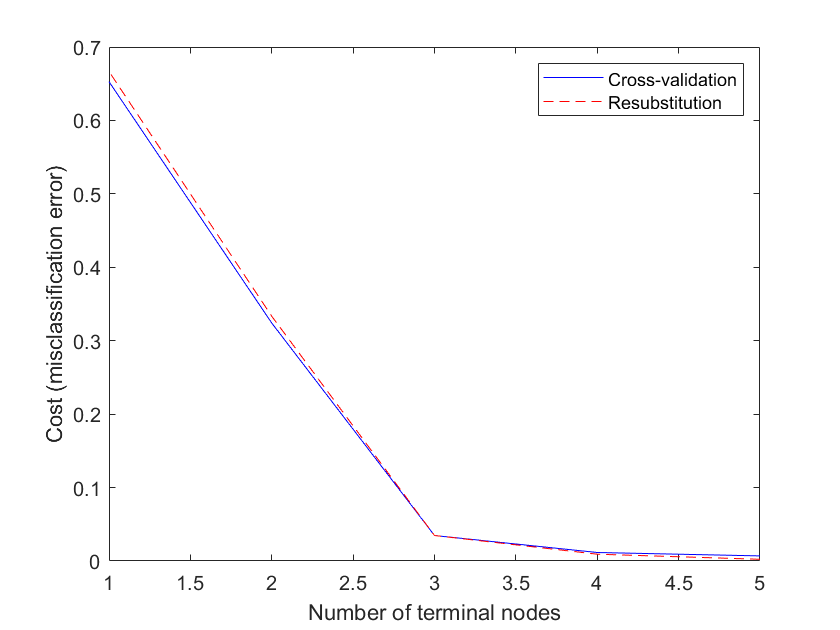

[cost,se_cost,n_leaf,bestlevel] = cvloss(t,'Subtrees','all');

plot(n_leaf,cost,'b-', n_leaf,resub_loss,'r--')
xlabel('Number of terminal nodes');
ylabel('Cost (misclassification error)')
legend('Cross-validation','Resubstitution')

% Prune Tree Levels
pt = prune(t,'Level',bestlevel);
cost(bestlevel+1)

ans = 0.0069

view(pt,'Mode','graph')

# Exercise

## Exercise 1: 

Now, Select any 3 features and repeat the process. 

**Features**

% Example
X(:, 1) = table2array(glob_all_train(:, "kv"));       % Kurtosis value of time data
X(:, 2) = table2array(glob_all_train(:, "mf"));       % Marginal-Factor
X(:, 3) = table2array(glob_all_train(:, "cf"));       % Marginal-Factor

Plot the test and train results in 3D graph.

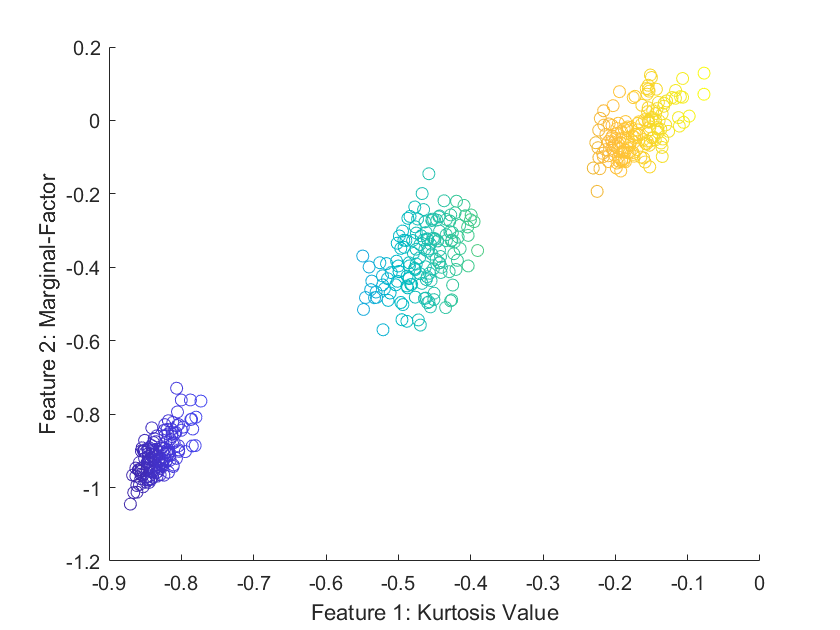

fig1 = figure;

tableX = glob_all_train(:,{'kv','mf','cf'});
hold on;
scatter3(tableX,'kv','mf','cf','ColorVariable','kv');
xlabel('Feature 1: Kurtosis Value');
ylabel('Feature 2: Marginal-Factor');
zlabel('Feature 3: Marginal-Factor');

Y = class_cwru_train; % fault class
N = size(X,1);
tbl=table(X(:, 1),X(:, 2),X(:, 3),Y);

Xtest(:, 1) = table2array(glob_all_test(:, "kv"));
Xtest(:, 2) = table2array(glob_all_test(:, "mf"));
Xtest(:, 3) = table2array(glob_all_test(:, "cf"));
Ytest = class_cwru_test;
Ntest=size(Xtest,1);
tblTest=table(Xtest(:, 1),Xtest(:, 2),Xtest(:, 3),Ytest);

rng(0)
cv = cvpartition(Y,'KFold',10) 

cv = K-겹 교차 검증 분할
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43

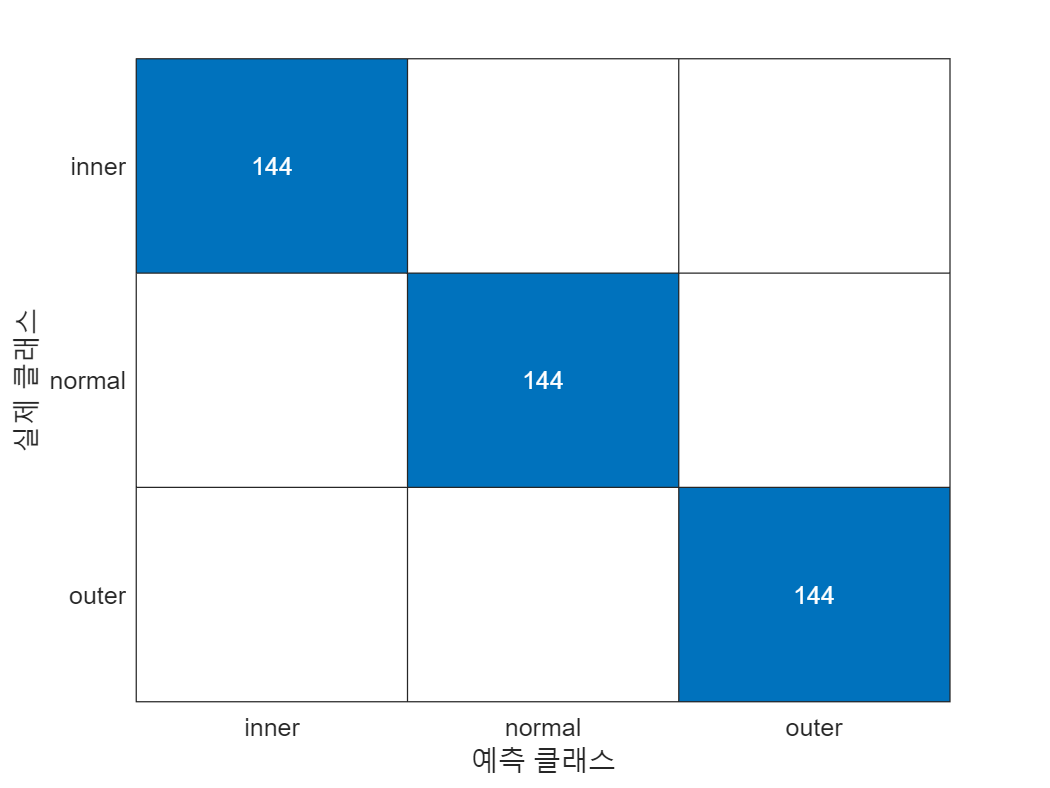

t = fitctree(X, Y,'PredictorNames',{'sv' 'ipf' 'cf' });
test_resub = resubLoss(t);

test_class = resubPredict(t);
figure;
tResubCM = confusionchart(Y,test_class);

bad = ~strcmp(test_class,Y);
figure(fig1); hold on;

plot(X(bad,1), X(bad,2), 'kp');




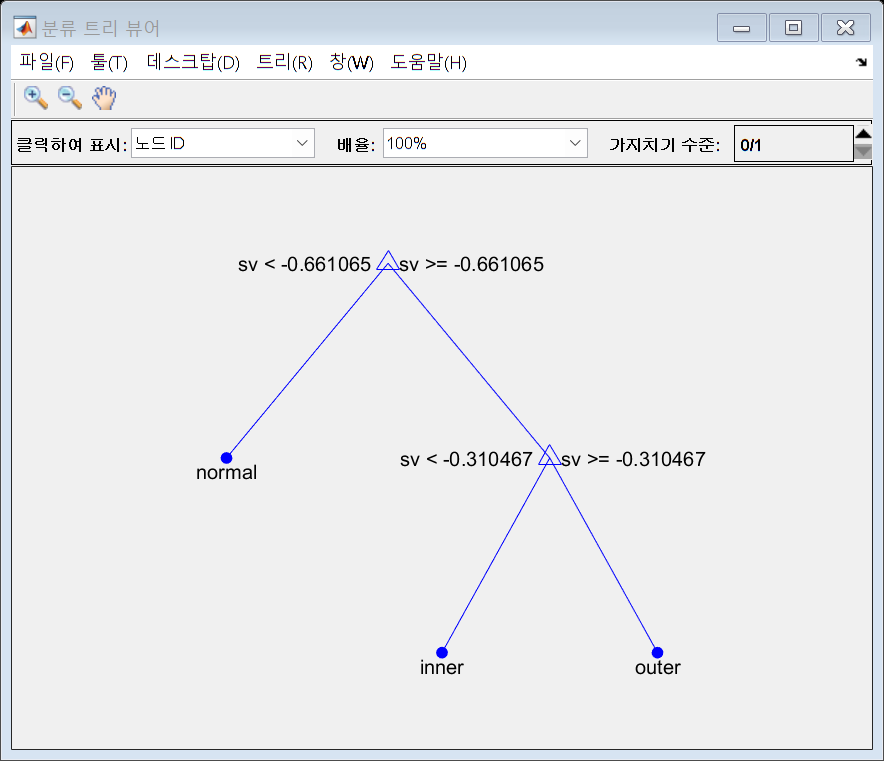

cross_val = crossval(t,'CVPartition',cv);
test_cv_error = kfoldLoss(cross_val);
view(t,'Mode','graph');

resub_loss = resubLoss(t,'Subtrees','all')

resub_loss =          0
    0.6667


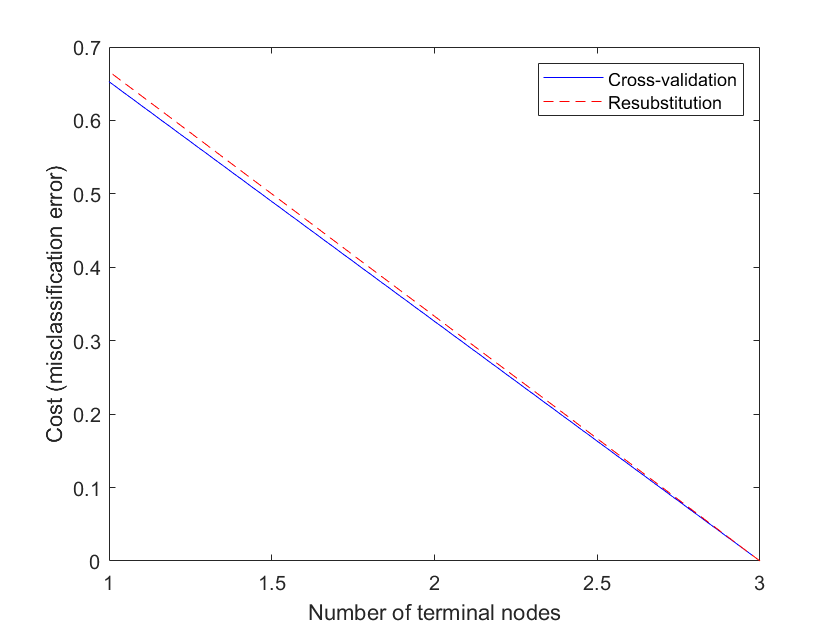


[cost,se_cost,n_leaf,best_level] = cvloss(t,'Subtrees','all');
figure; grid on;
plot(n_leaf,cost,'b-', n_leaf,resub_loss,'r--')
xlabel('Number of terminal nodes');
ylabel('Cost (misclassification error)')
legend('Cross-validation','Resubstitution')


pt = prune(t,'Level',best_level);
cost(best_level+1)

ans = 0

view(pt,'Mode','graph')

Compare performance with other classification 

Look for a random forest model in Matlab

Compared to Random forest, tree is simple but may not be robust to overfit.

Random forest model is tree-based and it is more robust and stable but may be slow

(Boosting)